# REDES NEURONALES PARA CLASIFICACIÓN

En este ejemplo de utilización de redes neuronales para clasificación se trabajará con el conjunto de datos de flores Iris de Ronald Fisher.

Fisher midió cuatro características de 50 ejemplares de tres especies Iris, largo y ancho de los sépalos y largo y ancho de los pétalos. Con este conjunto de medídas, en centímetros, Fisher desarrolló un modelo de clasificador lineal para distinguir entre las tres especies: setosa, versicolor y virginica.

# 1) Carga de los datos de flores Iris obtenidos por Ronald Fisher

Primero se cargan los datos en el espacio de trabajo de Matlab, ejecutando la siguiente instrucción en la ventana de comandos. Tras ejecutarla, aparecen las variables 'caracteristicas'  y 'clasificacion' en el espacio de trabajo. ¿Qué información contienen esas dos variables?

carga_datos_visualizacion

# 2) Visualización de los datos: ¿De qué manera podemos clasificar visualmente los datos en base a las características?

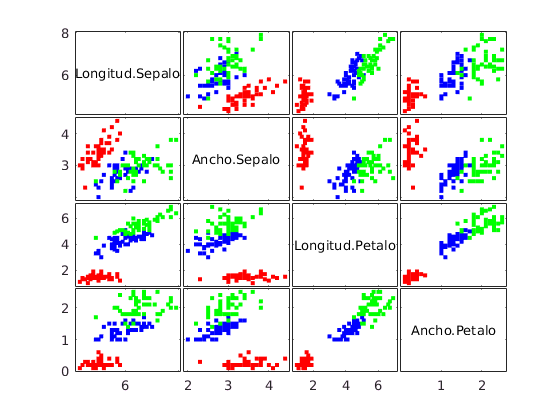

figure(1)
gplotmatrix(caracteristicas, [], clasificacion, ['r', 'b', 'g'],[],[],'off','variable',{'Longitud.Sepalo','Ancho.Sepalo','Longitud.Petalo','Ancho.Petalo'}); % Hacemos un plot enfrentando a todas las características

[media,std] = grpstats(caracteristicas,clasificacion,{'mean','std'})

media =     5.0060    3.4280    1.4620    0.2460
    5.9360    2.7700    4.2600    1.3260
    6.5880    2.9740    5.5520    2.0260


std =     0.3525    0.3791    0.1737    0.1054
    0.5162    0.3138    0.4699    0.1978
    0.6359    0.3225    0.5519    0.2747


¿Qué dos características eligirías para distinguir entre especies de Iris? ¿Cuál sería la peor elección?

# 3) Creación y entrenamiento de la red neuronal para clasificación de flores Iris

## 3.1) Se define la red

red = define_red;
view(red);

Describe la red, ¿cuántas capas ocultas tiene?

## 3.3) Se entrena a la red

carga_datos_entrenamiento;
[red_entrenada,info_entrenamiento] = entrena_red(red,caracteristicas,clasificacion);

## 3.4) En tercer lugar se procederá a la visualización de resultados: matrices de confunsion, curva roc, funcion de perdida.

Función de pérdida:

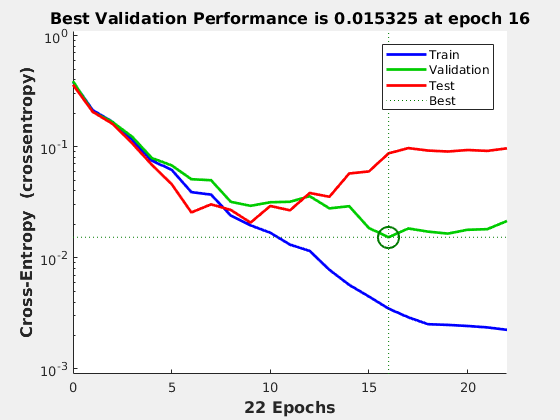

figure, plotperform(info_entrenamiento)

# 4) Utiliza la red para clasificar una flor Iris en base a sus características

## 4.1) Con ejemplares nuevo de flor (no vistos durante el entrenamiento)

floresNuevas=caracteristicas(:,info_entrenamiento.testInd);

## 4.2) Se utiliza la red con una de las flores nuevas

red_entrenada(floresNuevas(:,1))

ans =     0.9999
    0.0001
    0.0000


¿Cuál es la especie que clasifica la red?



[val,idx]=max(red_entrenada(floresNuevas))

val =     0.9999    1.0000    1.0000    0.9998    1.0000    1.0000    0.9998    1.0000    0.9999    1.0000    0.9999    1.0000    0.9976    0.9998    0.9998    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


idx =      1     1     1     1     1     1     1     1     2     2     2     2     3     2     2     2     3     3     3     3     3     3     3


¿Se ha equivocado la red? ¿Dónde?

# 4) Observa cómo se ha definido la red

type define_red.m


function [net] = define_red()

% Elige un algoritmo de backpropagation
% Puedes obtener una lista completa con: help nntrain

trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.
%trainFcn = 'traingd';  % Gradient descent backpropagation.
hiddenLayerSize = 10;
% Crea una red para clasificación
net = patternnet(hiddenLayerSize, trainFcn);
%net.trainParam.showWindow=1;
%net.trainParam.lr = 0.01;
%net.trainParam.epochs = 10000;

end
